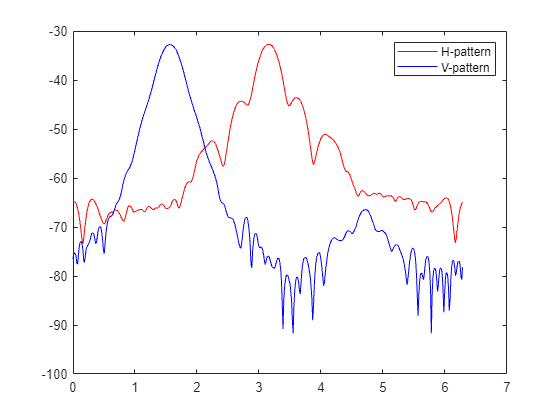

R = 10;

% Read data from csv file
data_hh = readtable("data/8 GHz H-H.txt");
data_vv = readtable("data/8 GHz V-V.txt");

% Rename two variables
data_hh = renamevars(data_hh, {'Var1','Var2'}, {'angle', 'power'});
data_vv = renamevars(data_vv, {'Var1','Var2'}, {'angle', 'power'});


% Transform both range to (0,360)
data_hh.angle = data_hh.angle + 180;
data_vv.angle = data_vv.angle + 180;

% Transform angles to radian
data_hh.angle = deg2rad(data_hh.angle);
data_vv.angle = deg2rad(data_vv.angle);

% Shift the vertical data so the main direction becomes 90
data_vv_1 = data_vv.power(1:125);
data_vv_2 = data_vv.power(126:end);
data_vv.power = vertcat(data_vv_2, data_vv_1);


% % Plot two radiation pattern
figure;
plot(data_hh.angle, data_hh.power, 'r-', data_hh.angle, data_vv.power, 'b-');
legend('H-pattern','V-pattern')

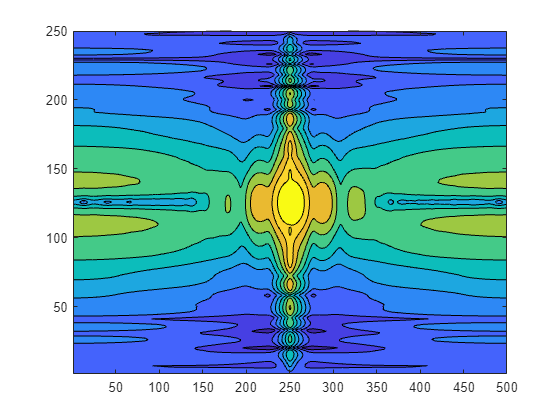


% Transform both to linear field pattern
data_hh.power = arrayfun(@log2linear, data_hh.power);
data_vv.power = arrayfun(@log2linear, data_vv.power);

% Normalize power
hh_power_max = max(data_hh.power);
data_hh.power = data_hh.power/hh_power_max;
vv_power_max = max(data_vv.power);
data_vv.power = data_vv.power/vv_power_max;



% extract the vertical front data
data_vv_front = table(data_vv.angle(1:250), data_vv.power(1:250), 'VariableNames', {'angle', 'power'});
% extract the vertical rear data
data_vv_rear = table(data_vv.angle(251:end), data_vv.power(251:end), 'VariableNames', {'angle', 'power'});

% create a 250*500 empty matrix
result = zeros(250, 500);


% Loop through all angles to get result
for h_index = 1:500
    for v_index = 1:250
        result(v_index, h_index) = interpolation(v_index, h_index, data_hh, data_vv_front, data_vv_rear);
    end
end


% Plot the heatmap in log scale
result_log = 10*log10(result);
figure;
contourf(result_log);

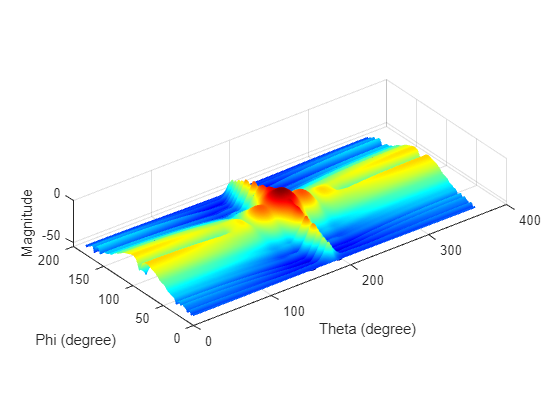


% Plot the pattern in 3D
plot_theta = rad2deg(data_vv_front.angle);
plot_phi = rad2deg(data_hh.angle);
figure;
patternCustom(result_log, plot_phi, plot_theta,'CoordinateSystem','rectangular');

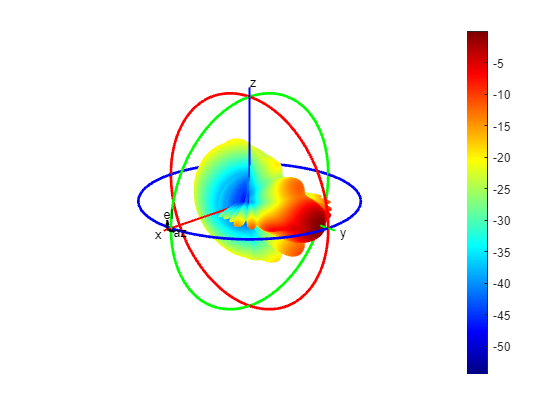

figure;
patternCustom(result_log, plot_phi-90, plot_theta);


result2 = result;

for index = 1:250
    result2(index,:) = result2(index,:) * sin(data_vv_front.angle(index));
end

result2 = result2';

P_total2 = trapz(data_hh.angle,trapz(data_vv_front.angle,result2,2))

P_total2 = 0.1661


D = (4*pi)/(P_total2)

D = 75.6563

function result = interpolation(v_index,h_index, data_hh, data_vv_front, data_vv_rear)
    theta = data_vv_front.angle(v_index);
    phi = data_hh.angle(h_index);
    numerator = data_hh.power(h_index)*sin(theta)^2;
    denomenator = data_vv_front.power(125)*cos(phi/2)^2+data_vv_rear.power(125)*sin(phi/2)^2;
    fun2 = data_vv_front.power(v_index)*cos(phi/2)^2+data_vv_rear.power(v_index)*sin(phi/2)^2;
    result = (numerator/denomenator+cos(theta)^2)*fun2;
end

function linear_value = log2linear(log_value)
    linear_value = 10^(log_value/10);
end